clear arduino;

    %connect to serial, re-run untill light tunrs on
    arduino = serialport("COM7", 115200);
    configureTerminator(arduino,"LF");

%print out serial data to make sure accel is working
serial_command(arduino, 400/10);
configureCallback(arduino,"terminator", @sample_data);
    

configureCallback(arduino, "off");
clc


num_data_points = 1000;
configureCallback(arduino, "off");
    %set up data struct to read
    arduino.UserData = struct("Data",zeros(num_data_points,3),"Count",1, "Points", num_data_points);
    
    serial_command(arduino, num_data_points/10);
    configureTerminator(arduino,"CR");
    flush(arduino);
    configureCallback(arduino,"terminator", @read_data);


    %clear arduino

configureCallback(arduino, "off");
    arduino.UserData.Data

ans =     59616432        1728    59609044
    59617308        2142    59609044
    59618185        2010    59609044
    59619061        1414    59609044
    59619938         466    59609044
    59620815        -628    59609044
    59621691        -628    59609044
    59622574       -1682    59622076
    59623450       -2408    59622076
    59624327       -2604    59622076


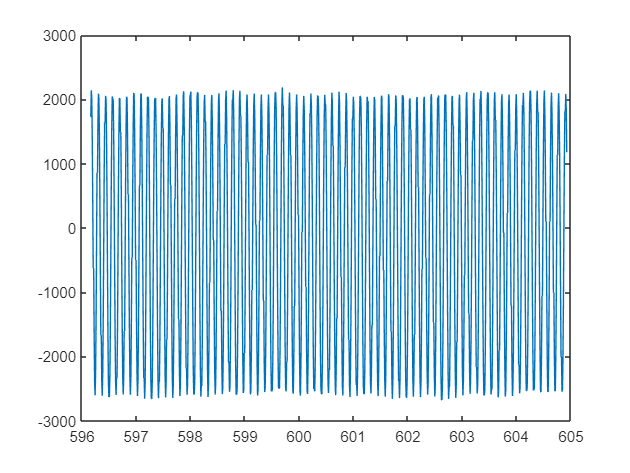




figure(1)
clf
plot(arduino.UserData.Data(:,1)/100000,arduino.UserData.Data(:,2))


data_array=[arduino.UserData.Data(:,1) - arduino.UserData.Data(1,1)    arduino.UserData.Data(:,2)  arduino.UserData.Data(:,3)- arduino.UserData.Data(1,1)]

data_array =            0        1728       -7388
         876        2142       -7388
        1753        2010       -7388
        2629        1414       -7388
        3506         466       -7388
        4383        -628       -7388
        5259        -628       -7388
        6142       -1682        5644
        7018       -2408        5644
        7895       -2604        5644


dt = []

dt =
     []


for i = 2:length(data_array(:,1))

    dt(end+1)= data_array(i,1) - data_array(i-1,1);
end
mean(dt)

ans = 877.3604

rpm = [];
for i = 2:length(data_array(:,1))
    if data_array(i,3) ~= data_array(i-1,3)
    rpm(end+1)= data_array(i,3) - data_array(i-1,3);
    end
end
 1 / (mean(rpm) / 1000000)

ans = 76.7222


figure(3)
clf
Y = fft(data_array(:,2));
Fs = 1/0.000877;
T = 1/Fs;
L = length(data_array(:,1))-1;

P2 = abs(Y/L);
P1 = P2(1:L/2+1);

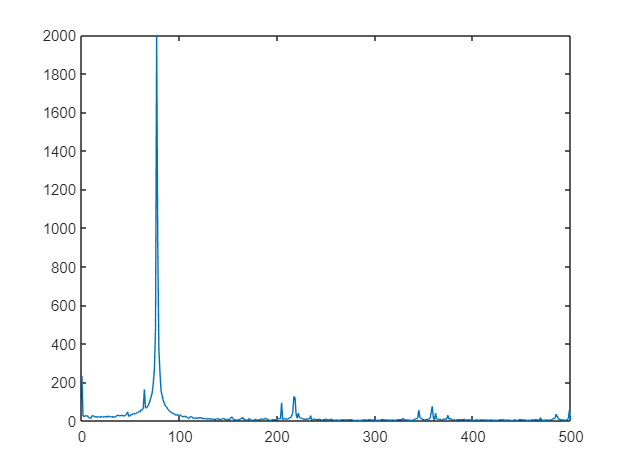

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1)
xlim([0,500])

serialportlist("available")

ans = "COM3"

clf
h = animatedline('MaximumNumPoints',100);
axis([0,4*pi,-1,1])

x = linspace(0,4*pi,1000);
y = sin(x);
for k = 1:length(x)
    addpoints(h,x(k),y(k));
    drawnow
end

figure(1)
clf
plot(arduino.UserData.Data(good_data,1),arduino.UserData.Data(good_data,2))


clear arduino

clear arduino


    %connect to serial
    arduino = serialport("COM7",9600);
    %set up line terminator
    configureTerminator(arduino,"CR/LF");
    %clear serial buffer
    flush(arduino);
    %set up data struct to read
    arduino.UserData = struct("Data",[],"Count",1);
    %run func. every time the "terminator
    % is detected


  configureCallback(arduino,"terminator", @read_data);
    


    

    function sample_data(src, ~)
    % Read the ASCII data from the serialport object.
    readline(src)
    end


    function read_data(src, ~)
    % Read the ASCII data from the serialport object.

    data = readline(src);

    data = split(data);
    data = str2double(data);

     %Convert the string data to numeric type and save it in the UserData
     %property of the serialport object.
     src.UserData.Data(src.UserData.Count,:) = [data(1) data(2) data(3)];
 
     % Update the Count value of the serialport object.
     src.UserData.Count = src.UserData.Count + 1;

  
     % If 1001 data points have been collected from the Arduino, switch off the
     % callbacks and plot the data.
         if src.UserData.Count > src.UserData.Points
            configureCallback(src, "off");
         end
    end

